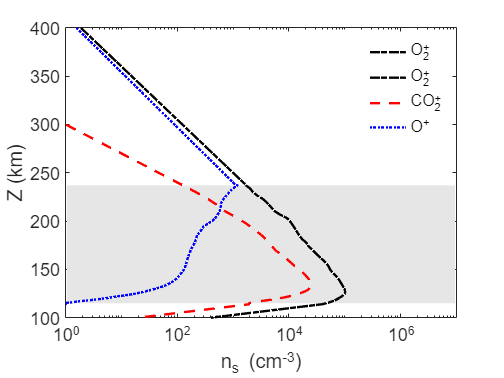

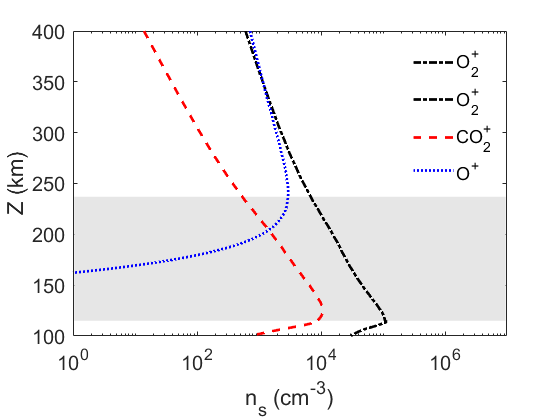

clearvars;
clc;

% Define path of input files to be read/written
root = 'C:/FloridaTech/Research/M4/input';
cd(root);

% Read in input files
profile_data = dlmread('RainaProfile.in', ' ', 1, 0);
partition_data = dlmread('RainaPartition.in', ' ', 1, 0);

% Compute ion densities
ne = profile_data(:,9);
ion_data = partition_data;
ion_data(:,2:4) = ion_data(:,2:4).*ne;

PlotPartition(ion_data);


% Handle Raina Data
eval_Raina = 0;
if (eval_Raina)
    [Raina_data, orig_Raina_data] = GetRainaHaider();
    PlotPartition(Raina_data)
    %PlotPartition(orig_Raina_data)
end


%WritePartition_givenEDensity('testPartition.in',Raina_data,ne);
%WriteProfile_givenIonDensities('testProfile.in',profile_data,Raina_data(:,2:4));

function PlotPartition(partition_data)
    figure;
    
    semilogx(partition_data(:,2)/1e6,partition_data(:,1)/1000,'DisplayName','O_2^+','LineWidth',2,'Color','k','LineStyle','-.')
    hold on;
    xlim([1e0 1e7]);
    ylim([100 400]);
    p = patch([min(xlim)+0.05 max(xlim)-500000, max(xlim)-500000 min(xlim)+0.05], [115 115 237 237], [0.9 0.9 0.9],'EdgeColor','none');
    p.Annotation.LegendInformation.IconDisplayStyle = 'off';
    semilogx(partition_data(:,2)/1e6,partition_data(:,1)/1000,'DisplayName','O_2^+','LineWidth',2,'Color','k','LineStyle','-.')
    semilogx(partition_data(:,3)/1e6,partition_data(:,1)/1000,'DisplayName','CO_2^+','LineWidth',2,'Color','r','LineStyle','--')
    semilogx(partition_data(:,4)/1e6,partition_data(:,1)/1000,'DisplayName','O^+','LineWidth',2,'Color','b','LineStyle',':')
    hold off;
    xlabel("n_s (cm^{-3})");
    ylabel("Z (km)");
    legend('show','Location','northeast');
    legend boxoff;
    set(gca,'FontSize',15)
end

function WritePartition_givenEDensity(f_name, partition_data, ne)
    line1 = "z         (m) x         O2+ x        CO2+ x          O+\n";
    formatSpec = "+%.6e +%.6e +%.6e +%.6e\n";
    fileID = fopen(f_name,'w');
    fprintf(fileID, line1);
    for i=1:length(partition_data(:,1))
        fprintf(fileID, formatSpec, partition_data(i,1), partition_data(i,2)/ne(i), partition_data(i,3)/ne(i), partition_data(i,4)/ne(i));
    end
    fclose('all');
end

function WriteProfile_givenIonDensities(f_name, profile_data, ion_data)
    line1 = "z         (m) Bx        (T) By        (T) Bz        (T) |B|       (T) O       (m-3) CO2     (m-3) ng      (m-3) ne      (m-3) Te        (K) Ti        (K) Tg        (K) nu_iz   (1/s) pe       (Pa) pO2+     (Pa) pCO2+    (Pa) pO+      (Pa) vs      (m/s)\n";
    formatSpec = "+%.6e +%.6e +%.6e +%.6e +%.6e +%.6e +%.6e +%.6e +%.6e +%.6e +%.6e +%.6e +%.6e +%.6e +%.6e +%.6e +%.6e +%.6e\n";
    fileID = fopen(f_name,'w');
    fprintf(fileID, line1);
    for i=1:length(profile_data(:,1))
        fprintf(fileID, formatSpec, ...
            profile_data(i,1), profile_data(i,2), profile_data(i,3), profile_data(i,4), ...
            profile_data(i,5), profile_data(i,6), profile_data(i,7), profile_data(i,8), ...
            sum(ion_data(i,:)), profile_data(i,10), profile_data(i,11), profile_data(i,12), ...
            profile_data(i,13), profile_data(i,14), profile_data(i,15), profile_data(i,16), ...
            profile_data(i,17), profile_data(i,18));
    end
    fclose('all');
end

function [theo, orig] = GetRainaHaider()

    % Organize raw data from Raina and Haider plot
    theoCO2 = [107.28443014544911, 238.81087784813934,186.81809528372952, 231.66782071435557,234.7542544916016, 228.73721448609507,314.6875438309644, 224.59740261321213,395.03062258963615, 221.05560394575534,464.5663141383297, 218.36082281080465,583.1088976231371, 214.75111387232602,706.8980779994838, 210.28593692918963,888.1486408313958, 207.26478367290005,1115.366197275364, 203.97198933252324,1355.6298531130644, 201.0461118658813,1647.6492681422417, 198.12023439923934,1936.9460712938242, 195.19908569421594,2202.083207554452, 192.19211872278197,4713.658420891596, 175.60064559651647,5408.092713513752, 171.41499100683157,5952.282040476774, 168.95603496519067,8496.361932707108, 162.52045311133625,9975.335409790083, 158.82965466806564,12094.845277034583, 154.45502475295834,23717.072856163344, 138.60053788190828,24352.137742153875, 134.46686464216347,24228.71247608603, 131.42448450038623,21823.663513818727, 128.6950958359606,16631.980222543043, 125.6769637329273,11868.059507423008, 123.16629780729107,7924.805887082224, 120.82354670394281,5296.532173844187, 119.02407776876905,3542.6070491965934, 117.67734397374073,2368.7705537823995, 116.14951612265423,1582.9248605572204, 114.25950015945139];
    j = 1;
    while j <= length(theoCO2)-1
        theoCO2x(ceil(j/2)) = theoCO2(j);
        theoCO2y(ceil(j/2)) = theoCO2(j+1);
        j = j+2;
    end
    tempO2 = [30716.31948711234, 113.83864037540133,47152.29831133881, 115.02766121348537,68868.39878425805, 118.34304852603967,90537.83835885575, 122.50056406510558,101597.60708683495, 124.98993596851514,101130.9232323651, 128.88503442763863,89302.21869106576, 134.22811472222295,81336.75599658009, 138.15393261793503,73250.23190306373, 141.97267033388505,63079.59146276196, 145.59398225226101,55546.61432835882, 149.26948811397637,50646.90116378556, 153.84422637723023,41837.88091825807, 159.1696000866429,37986.97917918481, 161.22109450215294,32362.254713340222, 165.0477134874672,27139.47268453116, 169.41997902176522,22749.762040949743, 173.53418552618035,20721.028505316535, 177.4735854760968,17636.859602341927, 180.75692229323653,15534.459851840646, 184.57881251693226,13708.773140758605, 189.54159529379444,9703.790463509347, 202.17059386483822,6779.688133550657, 206.9763292141691,5580.6283729526585, 210.1738477648983,4758.261881010145, 214.49847540437253,4190.103243889844, 218.18454508602463,3456.6103834335577, 222.69499554317554,2752.6528624501793, 226.0330633975669,2268.559894104719, 229.9549581725288,1998.7409193875378, 233.95794245228268,1645.9889733005732, 237.42710208709912];
    j = 1;
    while j <= length(tempO2)-1
        theoO2x(ceil(j/2)) = tempO2(j);
        theoO2y(ceil(j/2)) = tempO2(j+1);
        j = j+2;
    end
    tempO = [0.7937273274502612, 114.7491021262895,1.2100019186430861, 115.76702936344202,1.737870386168309, 117.01983594158062,2.64942610966869, 118.06492728714184,3.95994441352583, 119.23056702611197,5.921386363699842, 120.66784784916939,8.85771906416737, 122.33149624229952,13.24312670265674, 123.67823003732786,19.817699092943634, 125.56824600053068,29.678661595817765, 127.91099710387894,43.001413018341694, 130.4214616192981,60.30030820122635, 133.30789771125504,79.17156352437125, 136.69274527780613,94.01334775449823, 139.79297393671683,108.07692789910513, 143.4412135254206,120.14537647205104, 146.95836133369926,133.53115884527594, 150.33968859993433,145.9623927163447, 157.0744084109912,138.62657488932382, 152.8068937035098,155.82177194156677, 162.95208396351745,167.84926762636397, 167.5605248697637,174.40449980667086, 170.54384803310495,187.35565564568742, 173.52244243482767,208.79714372426574, 178.5336162055862,228.3734529267478, 185.63052412875942,217.09925658178955, 181.92440099505836,259.67559788477456, 189.37088699936515,289.21857173008755, 194.01987265800736,355.26075127163136, 197.43228715340135,436.38346126634383, 200.8447016487953,501.7764469216845, 204.6287617795427,570.8816677876953, 210.04455991946105,606.6152466081313, 218.45881325989996,602.2278199242932, 214.11255591450387,675.4503379316304, 222.9493416194913,805.1412358876071, 228.3358827361364,925.7933548660269, 232.11994286688378,1100.3438459377821, 235.76345369396898,1305.7293536175819, 238.45622072674882];
    j = 1;
    while j <= length(tempO)-1
        theoOx(ceil(j/2)) = tempO(j);
        theoOy(ceil(j/2)) = tempO(j+1);
        j = j+2;
    end
    
    % Determine a range of y values that can be used to interpolate
    % x values for all three ions.
    miny = ceil(max([min(theoO2y) min(theoCO2y) min(theoOy)]))
    maxy = floor(min([max(theoO2y) max(theoCO2y) max(theoOy)]))
    
    % Interpolate with 1 km resolution
    interpZ = (maxy:-1:miny)';
    interpO2x  = interp1(theoO2y,theoO2x,interpZ);
    interpCO2x = interp1(theoCO2y,theoCO2x,interpZ);
    interpOx   = interp1(theoOy,theoOx,interpZ);
    
    % Now we need to "make up" the remaining data from 400->100
    upperZ = (400:-1:(max(interpZ)+1))';
    lowerZ = ((min(interpZ)-1):-1:100)';
    
    % Define arbitrary functions to predict profile behavior
    func_upperO2p  = @(y) 10.^(3-(y-250)/55);
    func_lowerO2p  = @(y) 4*10.^((y-114)/7+4);
    func_upperCO2p = @(y) 10.^(3-(y-210)/30);
    func_lowerCO2p = @(y) 2*10.^((y-114)/7+3);
    func_upperOp   = @(y) 10.^(3-(y-240)/57);
    func_lowerOp   = @(y) 1*10.^((y-114)/2);
    
    % Evalute functions in remaining regions
    upperO2p  = func_upperO2p(upperZ);
    lowerO2p  = func_lowerO2p(lowerZ);
    upperCO2p = func_upperCO2p(upperZ);
    lowerCO2p = func_lowerCO2p(lowerZ);
    upperOp   = func_upperOp(upperZ);
    lowerOp   = func_lowerOp(lowerZ);
    
    % Combine data
    newO2x  = [upperO2p;interpO2x;lowerO2p];
    newCO2x = [upperCO2p;interpCO2x;lowerCO2p];
    newOx   = [upperOp;interpOx;lowerOp];
    newZ    = [upperZ;interpZ;lowerZ];
    
    % Output
    orig(:,1:4) = [interpZ interpO2x interpCO2x interpOx];
    theo(:,1:4) = [newZ newO2x newCO2x newOx];
    
    orig(:,1)   = orig(:,1)*1000;
    theo(:,1)   = theo(:,1)*1000;
    orig(:,2:4) = orig(:,2:4)*1e6;
    theo(:,2:4) = theo(:,2:4)*1e6;
end